# Run inference using a trained quantum neural network on Amazon Braket 

This script introduces how to run inference using a pre-trained quantum neural network (QNN) on Amazon Braket, providing quantum computing service, as part of time series analysis. Regarding the pre-trained QNN model, this script is going to use the network which had been trained to estimate ΔSoC (time difference State of Charge) in the other script (BatterySoC/Create_and_TrainModel/script_train_dsoc_qnn_model_on_classic_computer.mlx).

## Before you run this script

### A. Requirements for your host to submit tasks to Amazon Braket

This script requires the Deep Learning Toolbox, Statistics and Machine Learning Toolbox, and the [MATLAB Support Package for Quantum Computing](https://www.mathworks.com/matlabcentral/fileexchange/125425-matlab-support-package-for-quantum-computing) in addition to MATLAB. 

To check if the required toolboxes are installed, run `ver` on MATLAB command window. Run the following command to check if the required support package is installed.

matlabshared.supportpkg.getInstalled

                    Name                     Version Base Product
-------------------------------------------- ------- ------------
MATLAB Support Package for Quantum Computing 26.1.5


In addition, the `myPQCLayer` class and the `createPQC` function must be on MATLAB search path because the trained QNN invokes a quantum circuit called to Parameterized Quantum Circuit (PQC) as a custom layer.

which myPQCLayer

C:\MATLAB\work\R2026a\QNN\myPQCLayer.m  % myPQCLayer constructor


### B. Requirements on Amazon Web Service

#### i. Amazon Braket

It's strongly recommended to check whether a quantum device is available on the Amazon Console in advance because Amazon Braket is a shared computing resource. In particular, actual QPU devices are sometimes reserved by other users or might be offline status due to hardware maintenance.

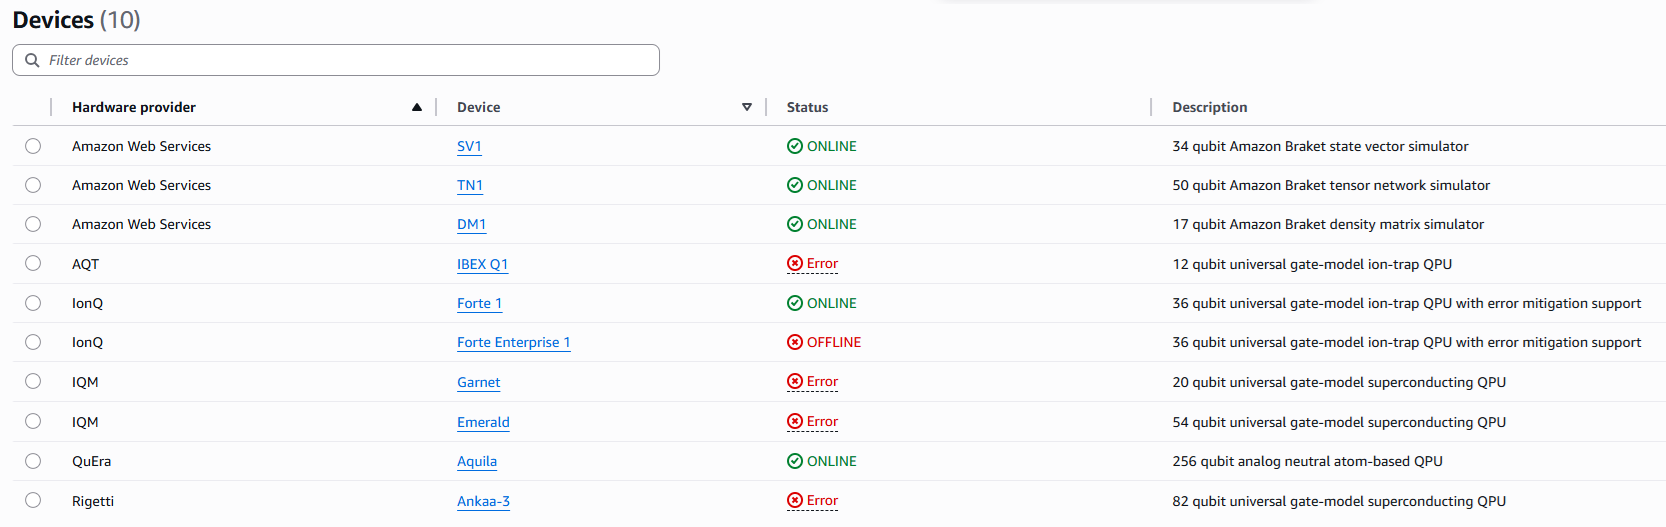

Fig.1 Example of Quantum Hardware Statuses provided by Amazon Braket

#### ii. Amazon S3

When you use Amazon Braket, you need to set up a folder in your bucket provided by Amazon S3 as a remote storage in advance. Because the output from device of Amazon Braket exported to the folder in your S3 bucket as a JSON file. 

Please note that it's required to begin with "**amazon\-braket\-**" as the name of your bucket to store Amazon Braket outputs. For instance, when we assume that we create the folder `my-test-bucket` in the `amazon-braket-mathworks` bucket, specify its path as follows:

S3URI  = "s3://amazon-braket-mathworks/my-test-bucket/";

**Notes: Please change the above **`S3URI`** appropriately depending on yours.**

On the MATLAB side, before submitting a task to Amazon Braket, it's required to set the following environment variables on MATLAB using [`setenv`](https://www.mathworks.com/help/matlab/ref/setenv.html).

- `AWS_DEFAULT_REGION`

- `AWS_ACCESS_KEY_ID`

- `AWS_SECRET_ACCESS_KEY`

- `AWS_SESSION_TOKEN (option)`

See below pages for details regarding S3 access

[Work with Remote Data](https://www.mathworks.com/help/matlab/import_export/work-with-remote-data.html)

[Work with Deep Learning Data in AWS](https://www.mathworks.com/help/deeplearning/ug/work-with-deep-learning-data-in-aws.html)

## 2. Import data and preprocess as preparing ΔSoC inference

### 2-1. Import data from the MAT-file

Import a timetable containing current, voltage, temperature and SoC data sampled every 4 seconds from the SocDataset.mat in the current folder. This data was acquired from one of the example provided by Simscape Battery, [Battery State-of-Charge Estimation](https://www.mathworks.com/help/simscape-battery/ug/battery-state-of-charge-estimation.html) and was downsampled to 0.25 Hz.

matobjData = matfile("SocDataset.mat");
dataSocTT0 = matobjData.dataTT_All;
dT = seconds(diff(dataSocTT0.Time(1:2))); % Sampling Time
numInputSignal = width(dataSocTT0) - 1; % Number of Input Signals

Align the height of `dataSocTT0` to match the length of data when the QNN model was trained.

idxValidEnd = find(dataSocTT0.Time == duration(5, 24, 4, 0, Format="s")); % extract until 5H 24M 4S
dataSocTT = dataSocTT0(1:idxValidEnd,:);

### 2-2. Prepare data corresponding to predictors

The QNN model to infer ΔSoC can be formulated out as follows:


$$\widehat{{\Delta \mathrm{SoC}}_t } =\varphi \left({\mathrm{Current}}_t ,{\mathrm{Current}}_{t-1} ,{\mathrm{Current}}_{t-2} ,{\mathrm{Current}}_{t-3} ,{\mathrm{Voltage}}_t ,{\mathrm{Voltage}}_{t-1} ,{\mathrm{Voltage}}_{t-2} ,{\mathrm{Voltage}}_{t-3} ,{\mathrm{Temperature}}_t ,{\mathrm{Temperature}}_{t-1} ,{\mathrm{Temperature}}_{t-2} ,{\mathrm{Temperature}}_{t-3} \right)$$


Before generating a timetable `xDataAll` taking into account of the predictor corresponding to the input variables of the above formula, calculate the parameters for standardization in the same way as when we created the model *φ*.

[~, OffsetsInSig, ScaleFactorsInSig] = normalize(dataSocTT(:,1:numInputSignal), range = [0,1]);

Let's generate the timetable `xDataAll` contained data before standardization.

LagOrder     = 3;
xDataAll = array2timetable(nan(height(dataSocTT), numInputSignal*(1+LagOrder)), RowTimes = dataSocTT.Time, ...
    VariableNames = reshape(transpose([transpose(string(dataSocTT.Properties.VariableNames(1:numInputSignal))) + "(t)", ...
                            transpose(string(dataSocTT.Properties.VariableNames(1:numInputSignal))) + "(t-1)", ...
                            transpose(string(dataSocTT.Properties.VariableNames(1:numInputSignal))) + "(t-2)", ...
                            transpose(string(dataSocTT.Properties.VariableNames(1:numInputSignal))) + "(t-3)"]), 1,12));

% current data
xDataAll.("Current(t)") = dataSocTT.Current;
xDataAll.("Current(t-1)")(2:end) = dataSocTT.Current(1:end-1);
xDataAll.("Current(t-2)")(3:end) = dataSocTT.Current(1:end-2);
xDataAll.("Current(t-3)")(4:end) = dataSocTT.Current(1:end-3);

% voltage data
xDataAll.("Voltage(t)") = dataSocTT.Voltage;
xDataAll.("Voltage(t-1)")(2:end) = dataSocTT.Voltage(1:end-1);
xDataAll.("Voltage(t-2)")(3:end) = dataSocTT.Voltage(1:end-2);
xDataAll.("Voltage(t-3)")(4:end) = dataSocTT.Voltage(1:end-3);

% temperature data
xDataAll.("Temperature(t)") = dataSocTT.Temperature;
xDataAll.("Temperature(t-1)")(2:end) = dataSocTT.Temperature(1:end-1);
xDataAll.("Temperature(t-2)")(3:end) = dataSocTT.Temperature(1:end-2);
xDataAll.("Temperature(t-3)")(4:end) = dataSocTT.Temperature(1:end-3);

Define `xDataAllN`, which is the actual predictor data, as the standardized output from `xDataAll`

xDataAllN = xDataAll;
xDataAllN{:,1:1+LagOrder} = (xDataAll{:,1:1+LagOrder} - OffsetsInSig.Current) ./ ScaleFactorsInSig.Current;
xDataAllN{:,1+1+LagOrder:2*(1+LagOrder)} = (xDataAll{:,1+1+LagOrder:2*(1+LagOrder)} - OffsetsInSig.Voltage) ./ ScaleFactorsInSig.Voltage;
xDataAllN{:,1+2*(1+LagOrder):3*(1+LagOrder)} = (xDataAll{:,1+2*(1+LagOrder):3*(1+LagOrder)} - OffsetsInSig.Temperature) ./ ScaleFactorsInSig.Temperature;

### 2-3. Prepare data corresponding to response

Generate data equivalent to ΔSoC which corresponds to the output of the model *φ*.

socDiffTable = diff(0.01.*dataSocTT(:,"SoC (Act)"));
socDiffTable.Time = socDiffTable.Time + seconds(dT);
socDiffTable = [timetable(NaN, RowTimes = seconds(0), VariableNames = "SoC (Act)"); socDiffTable];
socDiffTable.Properties.VariableNames(1) = "dSoC";

We don't need to standardize this response data but need to re-scale the output from the pre-trained QNN model. So we obtain its parameters for standardization.

ScaleFactorYn = max(socDiffTable.dSoC) - min(socDiffTable.dSoC);
OffsetYn = min(socDiffTable.dSoC);

## 3. Import the pre-trained quantum neural network

Import the pre-trained QNN including a Parameterized Quantum Circuit (PQC) from the MAT-file `SocDiff3Lag100EpochsTrainedNetwork.mat`.

matobjTrainedNet  = matfile("SocDiff3Lag100EpochsTrainedNetwork");
net = matobjTrainedNet.net;

Please note that the output of this pre-trained network is suppressed to within [0,1]. Therefore, we need to re-scale it to the original range of ΔSoC by using the standardization parameters, ScaleFactorYn and OffsetYn, calculated in the section 2-3 Prepare data corresponding to response.

## 4. Infer on your classical computer

We don't estimate over the periods of entire imported data, but focus on certain periods of 10 minutes charging and discharging. Regarding to the 10 minutes charging period, it begins at 12 (= 0 + `dT*LagOder`) seconds and the SoC was 50% at the 0 seconds. On the other hand, the 10 minutes discharging period, is starts from 4200 seconds when the SoC reached at approximately 50% again.

idxChargeS = 1 + LagOrder;
idxChargeE = find(xDataAllN.Time == duration(0, 10, dT*LagOrder, 0, Format="s"));

idxDischgS = find(xDataAllN.Time == duration(1, 10, 0, 0, Format="s")); % 4200s --> 1h : 10m : 00s
idxDischgE = idxDischgS + 10*60/dT;

yDataCharge = socDiffTable.dSoC(idxChargeS:idxChargeE);
yDataDischg = socDiffTable.dSoC(idxDischgS:idxDischgE);

Run inference for ΔSoC over the 10 minutes charging and discharging period on the classical computer and calculate the inference errors using mean squared error (MSE) after re-scaling with the standardization parameters.

yHatChargeCls = predict(net,xDataAllN{idxChargeS:idxChargeE,:});
MseChargeCls = sum(((ScaleFactorYn*yHatChargeCls + OffsetYn)  - yDataCharge).^2) ./ numel(yDataCharge);
disp("MSE (10 min. charging period): " + string(MseChargeCls))

MSE (10 min. charging period): 1.1219e-07


yHatDischgCls = predict(net,xDataAllN{idxDischgS:idxDischgE,:});
MseDischgCls = sum(((ScaleFactorYn*yHatDischgCls + OffsetYn)  - yDataDischg).^2) ./ numel(yDataDischg);
disp("MSE (10 min. discharging period): " + string(MseDischgCls))

MSE (10 min. discharging period): 7.7743e-07


## 5. Visualize the results of inference on the classical computer and their ground truth

Let's plot the estimated ΔSoC values and SoC values, which are obtained as cumulative sum of ΔSoC based on each initial value of charging and discharging period respectively.

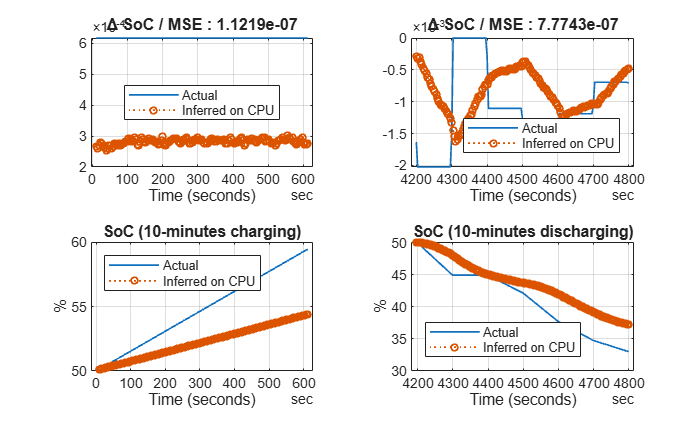

figure; tiledlayout(2,2)

axH01 = nexttile;
plot(axH01, socDiffTable.Time(idxChargeS:idxChargeE), socDiffTable.dSoC(idxChargeS:idxChargeE), LineWidth = 1)
hold(axH01, "on")
plot(axH01, socDiffTable.Time(idxChargeS:idxChargeE), ScaleFactorYn*yHatChargeCls + OffsetYn, LineWidth = 1, LineStyle = ":", Marker = "o" ,MarkerSize = 4)
title(axH01, "\Delta SoC / MSE : " + string(MseChargeCls))
xlabel(axH01, 'Time (seconds)')
legend(axH01, ["Actual", "Inferred on CPU"], Location = "best");
grid(axH01, "on")
hold(axH01, "off")

axH02 = nexttile;
plot(axH02, socDiffTable.Time(idxDischgS:idxDischgE), socDiffTable.dSoC(idxDischgS:idxDischgE), LineWidth = 1)
hold(axH02, "on")
plot(axH02, socDiffTable.Time(idxDischgS:idxDischgE), ScaleFactorYn*yHatDischgCls + OffsetYn, LineWidth = 1, LineStyle = ":", Marker = "o",MarkerSize = 4)
title(axH02, "\Delta SoC / MSE : " + string(MseDischgCls))
xlabel(axH02, 'Time (seconds)')
legend(axH02, ["Actual", "Inferred on CPU"], Location = "southeast");
grid(axH02, "on")
hold(axH02, "off")

axH03 = nexttile;
plot(axH03, dataSocTT.Time(1:idxChargeE), dataSocTT.("SoC (Act)")(1:idxChargeE), LineWidth = 1)
hold(axH03, "on")
plot(axH03, dataSocTT.Time(LagOrder:idxChargeE), dataSocTT.("SoC (Act)")(LagOrder) + [0; 100*cumsum(ScaleFactorYn*yHatChargeCls + OffsetYn)], ...
    LineWidth = 1, LineStyle = ":", Marker = "o" ,MarkerSize = 4)
title(axH03, "SoC (10-minutes charging)")
xlabel(axH03, 'Time (seconds)')
ylabel(axH03, "%")
legend(axH03, ["Actual", "Inferred on CPU"], Location = "northwest");
grid(axH03, "on")
hold(axH03, "off")

axH04 = nexttile;
plot(axH04, dataSocTT.Time(idxDischgS-1:idxDischgE), dataSocTT.("SoC (Act)")(idxDischgS-1:idxDischgE), LineWidth = 1)
hold(axH04, "on")
plot(axH04, dataSocTT.Time(idxDischgS-1:idxDischgE), dataSocTT.("SoC (Act)")(idxDischgS-1) + [0; 100*cumsum(ScaleFactorYn*yHatDischgCls + OffsetYn)], ...
    LineWidth = 1, LineStyle = ":", Marker = "o" ,MarkerSize = 4)
title(axH04, "SoC (10-minutes discharging)")
xlabel(axH04, 'Time (seconds)')
ylabel(axH04, "%")
legend(axH04, ["Actual", "Inferred on CPU"], Location = "southwest");
grid(axH04, "on")
hold(axH04, "off")

Fig.2 Inferred ΔSoC/SoC vs. their ground truth

There 4 axes in the above figure and blue lines are actual measured ΔSoC or SoC and red lines with circle marker are their inferred values on the classical computer. The upper axes display 2 graphs about the actual and inferred ΔSoC values and the lower axes display 2 graphs about the actual and inferred SoC using cumulative sum of ΔSoC values. The left axes correspond to 10-minutes charging period and the right axes correspond to 10-minutes discharging period.

## 6. Infer on a QPU device in Amazon Braket

We have worked the SoC inference task on the classical computer until the chaper 5, but in the chapter 6, we're going to a quantum processing unit (QPU) provided by Amazon Braket. It's specified to use not a actual QPU device but a simulator in this script. If you want to submit your tasks to the actual QPU, define the variable to to its ARN identifier.

### 6-1. Select a QPU device on Amazon Braket

First, we need to select a QPU device from the [AWS console](https://console.aws.amazon.com/console/home). The size of circuit, called parameterized quantum circuit (PQC), in the QNN model `net` to estimate ΔSoC is 13 qubits as follows:

disp(1 + width(xDataAllN))

    13



Therefore, we select the `DM1` QPU simulator supporting quantum circuits with up to 17 qubits.

DeviceURI = "arn:aws:braket:::device/quantum-simulator/amazon/dm1";
QpuDevice = quantum.backend.QuantumDeviceAWS(DeviceURI, S3Path = S3URI, Region = "us-east-1");

*Notes : We are required to specify the *`Region`* property when we use a QPU simulator.*

### 6-2. Retrieve learnable parameters in the QNN model

Retrieve the learnable parameters in the PQC layer corresponding to the ansatz after 100 epochs training on the classical computer.

trainedParams = net.Layers(2).Params;

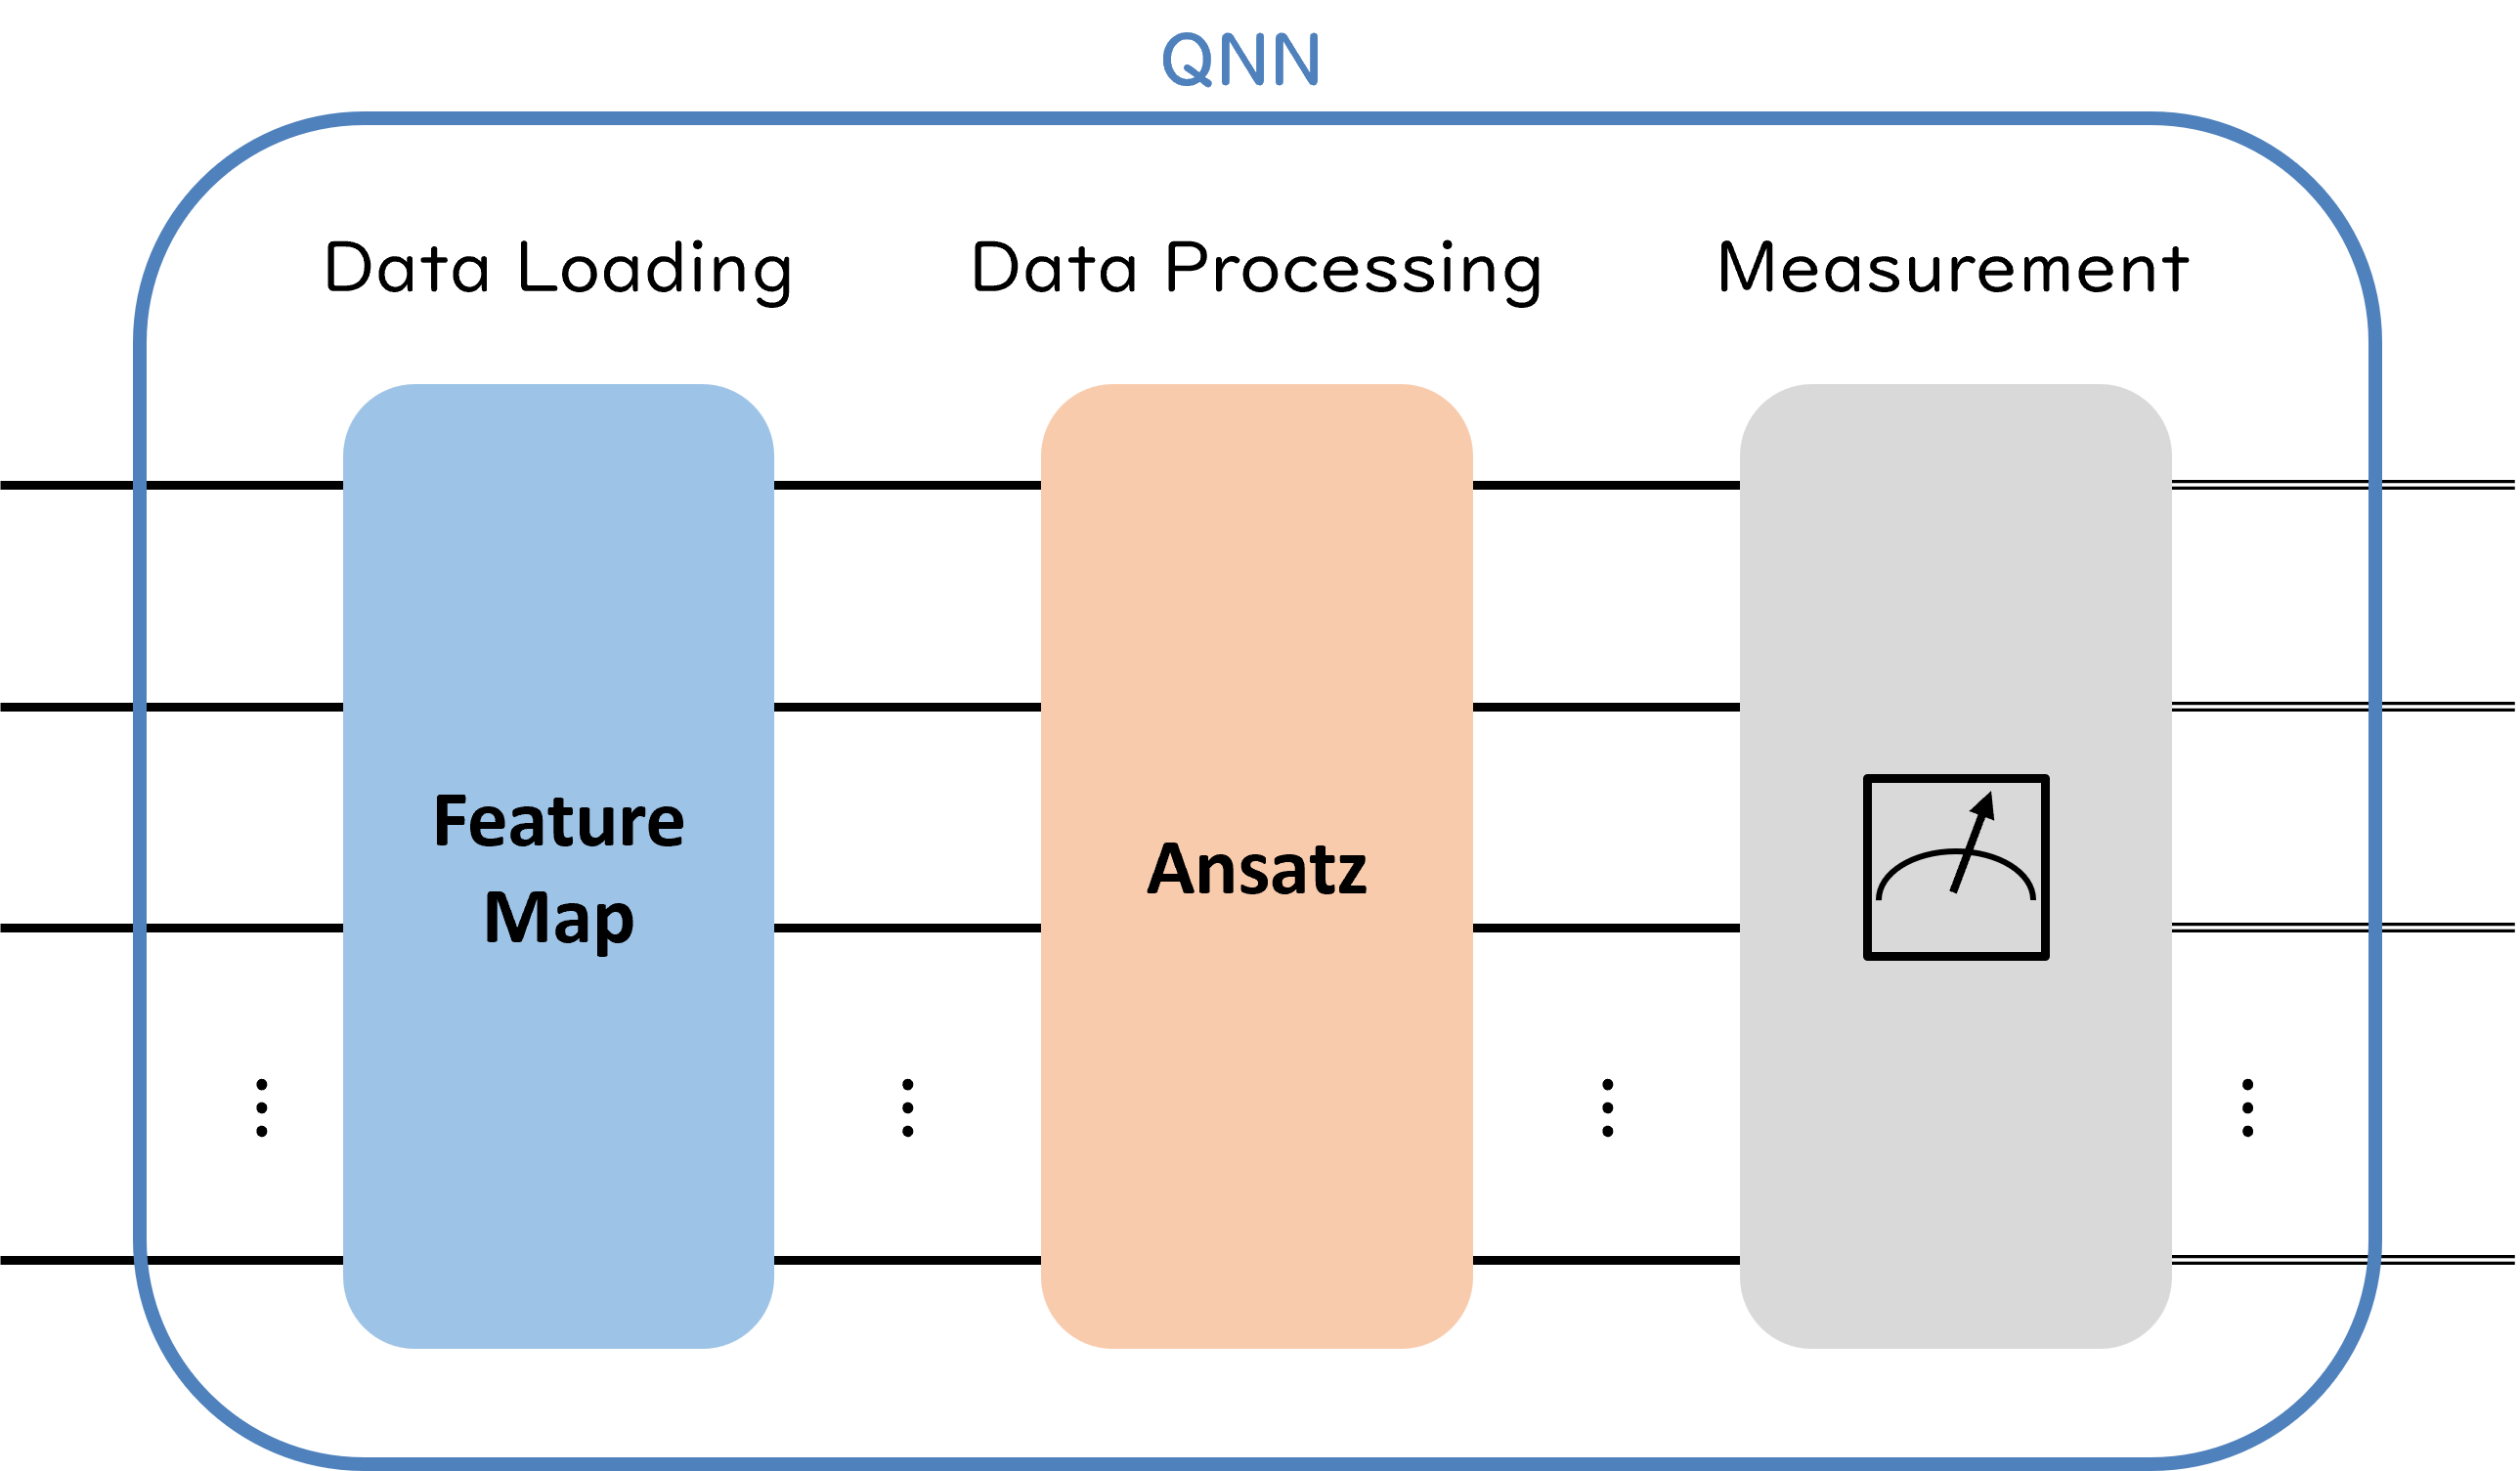

Fig.3 Architecture of General Quantum Neural Network

### 6-3. Define the observable object 

Create an object corresponding to the measurement layer in the above figure.

obsPauli = observable([repmat('I',1,width(xDataAllN)),'Z'], 1);

### 6-4. Infer the ΔSoC values on the device of Amazon Braket

Let's run the inference for the 10-minutes charging period (equivalent to 151 tasks) on the quantum hardware provided by Amazon Braket.

yHatChargeQpu = nan(numel(yDataCharge),1);

cumElpTime = 0;
for nSmplCharge = 0:numel(yDataCharge)-1

    % create the parameterized quantum circuit to run on Amazon Braket
    qCircuit = createPQC(xDataAllN{idxChargeS+nSmplCharge,:}, trainedParams); % set the trained learnable parameters

    % Run the quantum circuit on the AWS simulator
    task = run(qCircuit, QpuDevice, Observable = obsPauli, NumShots = 10000);

    % wait for quantum task until it's finished
    sTime = tic;
    wait(task);
    eTime = toc(sTime);

    % retrieve the results of submitted quantum task
    results = fetchOutput(task);

    % get the measured numeric expectation value
    yHatChargeQpu(1+nSmplCharge) = 0.5 * (1 + results);
    disp("Task # " + string(1+nSmplCharge) + " / " + string(numel(yDataCharge)) + " :: QPU Device (" ...
        + QpuDevice.Name + ")  : " + string(yHatChargeQpu(1+nSmplCharge)) + " / Classical Computer : " + string(yHatChargeCls(1+nSmplCharge)))

    % show the elapsed time for the current task
    disp("Elapsed time is " + string(eTime) + " seconds.")
    disp(newline)

    % update cumulo-elapsed time for estimating dSoC for the discharging period
    cumElpTime = eTime + cumElpTime;
end

Task # 1 / 151 :: QPU Device (dm1)  : 0.8779 / Classical Computer : 0.87689


Elapsed time is 8.1697 seconds.


Task # 2 / 151 :: QPU Device (dm1)  : 0.8808 / Classical Computer : 0.87564


Elapsed time is 5.6618 seconds.


Task # 3 / 151 :: QPU Device (dm1)  : 0.8808 / Classical Computer : 0.87895


Elapsed time is 5.5756 seconds.


Task # 4 / 151 :: QPU Device (dm1)  : 0.8803 / Classical Computer : 0.88164


Elapsed time is 5.5291 seconds.


Task # 5 / 151 :: QPU Device (dm1)  : 0.8839 / Classical Computer : 0.88092


Elapsed time is 5.7448 seconds.


Task # 6 / 151 :: QPU Device (dm1)  : 0.8807 / Classical Computer : 0.87904


Elapsed time is 6.1948 seconds.


Task # 7 / 151 :: QPU Device (dm1)  : 0.8753 / Classical Computer : 0.87579


Elapsed time is 5.1654 seconds.


Task # 8 / 151 :: QPU Device (dm1)  : 0.8753 / Classical Computer : 0.87289


Elapsed time is 5.8353 seconds.


Task # 9 / 151 :: QPU Device (dm1)  : 0.8791 / Classical Computer : 0.87531


Elapsed time is 5.7052 seconds.


Task # 10 / 151 :: QPU Device (dm1)  : 0.8775 / Classical Computer : 0.87837


Elapsed time is 5.6126 seconds.


Task # 11 / 151 :: QPU Device (dm1)  : 0.8838 / Classical Computer : 0.87864


Elapsed time is 5.6776 seconds.


Task # 12 / 151 :: QPU Device (dm1)  : 0.8766 / Classical Computer : 0.87534


Elapsed time is 5.7175 seconds.


Task # 13 / 151 :: QPU Device (dm1)  : 0.8724 / Classical Computer : 0.87702


Elapsed time is 5.5471 seconds.


Task # 14 / 151 :: QPU Device (dm1)  : 0.8783 / Classical Computer : 0.88102


Elapsed time is 5.6444 seconds.


Task # 15 / 151 :: QPU Device (dm1)  : 0.8842 / Classical Computer : 0.87954


Elapsed time is 5.7187 seconds.


Task # 16 / 151 :: QPU Device (dm1)  : 0.8725 / Classical Computer : 0.8788


Elapsed time is 5.743 seconds.


Task # 17 / 151 :: QPU Device (dm1)  : 0.8803 / Classical Computer : 0.88044


Elapsed time is 6.1494 seconds.


Task # 18 / 151 :: QPU Device (dm1)  : 0.879 / Classical Computer : 0.87899


Elapsed time is 5.7088 seconds.


Task # 19 / 151 :: QPU Device (dm1)  : 0.8804 / Classical Computer : 0.88087


Elapsed time is 5.7269 seconds.


Task # 20 / 151 :: QPU Device (dm1)  : 0.8819 / Classical Computer : 0.88133


Elapsed time is 4.5069 seconds.


Task # 21 / 151 :: QPU Device (dm1)  : 0.8826 / Classical Computer : 0.88229


Elapsed time is 5.7463 seconds.


Task # 22 / 151 :: QPU Device (dm1)  : 0.8778 / Classical Computer : 0.88251


Elapsed time is 5.7263 seconds.


Task # 23 / 151 :: QPU Device (dm1)  : 0.8822 / Classical Computer : 0.88291


Elapsed time is 5.083 seconds.


Task # 24 / 151 :: QPU Device (dm1)  : 0.8884 / Classical Computer : 0.88623


Elapsed time is 5.6612 seconds.


Task # 25 / 151 :: QPU Device (dm1)  : 0.8864 / Classical Computer : 0.88521


Elapsed time is 5.9285 seconds.


Task # 26 / 151 :: QPU Device (dm1)  : 0.8833 / Classical Computer : 0.88336


Elapsed time is 5.5934 seconds.


Task # 27 / 151 :: QPU Device (dm1)  : 0.8885 / Classical Computer : 0.88453


Elapsed time is 5.786 seconds.


Task # 28 / 151 :: QPU Device (dm1)  : 0.8882 / Classical Computer : 0.888


Elapsed time is 5.6756 seconds.


Task # 29 / 151 :: QPU Device (dm1)  : 0.8823 / Classical Computer : 0.88536


Elapsed time is 5.6342 seconds.


Task # 30 / 151 :: QPU Device (dm1)  : 0.8799 / Classical Computer : 0.87914


Elapsed time is 6.1781 seconds.


Task # 31 / 151 :: QPU Device (dm1)  : 0.8783 / Classical Computer : 0.87905


Elapsed time is 5.7701 seconds.


Task # 32 / 151 :: QPU Device (dm1)  : 0.8879 / Classical Computer : 0.88353


Elapsed time is 5.1492 seconds.


Task # 33 / 151 :: QPU Device (dm1)  : 0.8892 / Classical Computer : 0.8879


Elapsed time is 5.273 seconds.


Task # 34 / 151 :: QPU Device (dm1)  : 0.8869 / Classical Computer : 0.88533


Elapsed time is 5.6126 seconds.


Task # 35 / 151 :: QPU Device (dm1)  : 0.8838 / Classical Computer : 0.88306


Elapsed time is 5.5384 seconds.


Task # 36 / 151 :: QPU Device (dm1)  : 0.8809 / Classical Computer : 0.88245


Elapsed time is 5.448 seconds.


Task # 37 / 151 :: QPU Device (dm1)  : 0.8844 / Classical Computer : 0.88369


Elapsed time is 5.5641 seconds.


Task # 38 / 151 :: QPU Device (dm1)  : 0.8879 / Classical Computer : 0.88634


Elapsed time is 6.2573 seconds.


Task # 39 / 151 :: QPU Device (dm1)  : 0.8874 / Classical Computer : 0.88382


Elapsed time is 5.6566 seconds.


Task # 40 / 151 :: QPU Device (dm1)  : 0.887 / Classical Computer : 0.88402


Elapsed time is 5.6601 seconds.


Task # 41 / 151 :: QPU Device (dm1)  : 0.8859 / Classical Computer : 0.88554


Elapsed time is 5.564 seconds.


Task # 42 / 151 :: QPU Device (dm1)  : 0.8847 / Classical Computer : 0.88323


Elapsed time is 5.7858 seconds.


Task # 43 / 151 :: QPU Device (dm1)  : 0.8839 / Classical Computer : 0.88197


Elapsed time is 5.7546 seconds.


Task # 44 / 151 :: QPU Device (dm1)  : 0.8781 / Classical Computer : 0.88264


Elapsed time is 6.1461 seconds.


Task # 45 / 151 :: QPU Device (dm1)  : 0.883 / Classical Computer : 0.88017


Elapsed time is 6.2652 seconds.


Task # 46 / 151 :: QPU Device (dm1)  : 0.8835 / Classical Computer : 0.8807


Elapsed time is 5.4765 seconds.


Task # 47 / 151 :: QPU Device (dm1)  : 0.8928 / Classical Computer : 0.88395


Elapsed time is 6.2144 seconds.


Task # 48 / 151 :: QPU Device (dm1)  : 0.8872 / Classical Computer : 0.88845


Elapsed time is 6.0259 seconds.


Task # 49 / 151 :: QPU Device (dm1)  : 0.8827 / Classical Computer : 0.87992


Elapsed time is 5.5675 seconds.


Task # 50 / 151 :: QPU Device (dm1)  : 0.8816 / Classical Computer : 0.87831


Elapsed time is 5.7414 seconds.


Task # 51 / 151 :: QPU Device (dm1)  : 0.881 / Classical Computer : 0.88023


Elapsed time is 5.1738 seconds.


Task # 52 / 151 :: QPU Device (dm1)  : 0.8832 / Classical Computer : 0.88202


Elapsed time is 5.7194 seconds.


Task # 53 / 151 :: QPU Device (dm1)  : 0.8808 / Classical Computer : 0.88257


Elapsed time is 5.9386 seconds.


Task # 54 / 151 :: QPU Device (dm1)  : 0.881 / Classical Computer : 0.88385


Elapsed time is 5.548 seconds.


Task # 55 / 151 :: QPU Device (dm1)  : 0.8878 / Classical Computer : 0.88502


Elapsed time is 5.5864 seconds.


Task # 56 / 151 :: QPU Device (dm1)  : 0.8862 / Classical Computer : 0.88634


Elapsed time is 5.5308 seconds.


Task # 57 / 151 :: QPU Device (dm1)  : 0.884 / Classical Computer : 0.88654


Elapsed time is 5.6857 seconds.


Task # 58 / 151 :: QPU Device (dm1)  : 0.8847 / Classical Computer : 0.88658


Elapsed time is 5.1372 seconds.


Task # 59 / 151 :: QPU Device (dm1)  : 0.8847 / Classical Computer : 0.88316


Elapsed time is 5.5874 seconds.


Task # 60 / 151 :: QPU Device (dm1)  : 0.8803 / Classical Computer : 0.88166


Elapsed time is 6.026 seconds.


Task # 61 / 151 :: QPU Device (dm1)  : 0.8791 / Classical Computer : 0.88108


Elapsed time is 5.5231 seconds.


Task # 62 / 151 :: QPU Device (dm1)  : 0.8836 / Classical Computer : 0.88291


Elapsed time is 5.9965 seconds.


Task # 63 / 151 :: QPU Device (dm1)  : 0.8894 / Classical Computer : 0.8851


Elapsed time is 5.6105 seconds.


Task # 64 / 151 :: QPU Device (dm1)  : 0.888 / Classical Computer : 0.88654


Elapsed time is 6.0758 seconds.


Task # 65 / 151 :: QPU Device (dm1)  : 0.8879 / Classical Computer : 0.8881


Elapsed time is 6.5852 seconds.


Task # 66 / 151 :: QPU Device (dm1)  : 0.8865 / Classical Computer : 0.88517


Elapsed time is 5.6451 seconds.


Task # 67 / 151 :: QPU Device (dm1)  : 0.8796 / Classical Computer : 0.88116


Elapsed time is 5.565 seconds.


Task # 68 / 151 :: QPU Device (dm1)  : 0.8793 / Classical Computer : 0.88082


Elapsed time is 5.4341 seconds.


Task # 69 / 151 :: QPU Device (dm1)  : 0.8748 / Classical Computer : 0.88234


Elapsed time is 6.075 seconds.


Task # 70 / 151 :: QPU Device (dm1)  : 0.8818 / Classical Computer : 0.8845


Elapsed time is 6.1496 seconds.


Task # 71 / 151 :: QPU Device (dm1)  : 0.886 / Classical Computer : 0.88527


Elapsed time is 6.0511 seconds.


Task # 72 / 151 :: QPU Device (dm1)  : 0.882 / Classical Computer : 0.88546


Elapsed time is 5.6326 seconds.


Task # 73 / 151 :: QPU Device (dm1)  : 0.8894 / Classical Computer : 0.88756


Elapsed time is 6.1173 seconds.


Task # 74 / 151 :: QPU Device (dm1)  : 0.8866 / Classical Computer : 0.88461


Elapsed time is 5.7681 seconds.


Task # 75 / 151 :: QPU Device (dm1)  : 0.8832 / Classical Computer : 0.88366


Elapsed time is 5.6983 seconds.


Task # 76 / 151 :: QPU Device (dm1)  : 0.889 / Classical Computer : 0.885


Elapsed time is 6.1786 seconds.


Task # 77 / 151 :: QPU Device (dm1)  : 0.8867 / Classical Computer : 0.88228


Elapsed time is 5.782 seconds.


Task # 78 / 151 :: QPU Device (dm1)  : 0.8779 / Classical Computer : 0.88117


Elapsed time is 5.5557 seconds.


Task # 79 / 151 :: QPU Device (dm1)  : 0.8801 / Classical Computer : 0.88181


Elapsed time is 6.2953 seconds.


Task # 80 / 151 :: QPU Device (dm1)  : 0.8787 / Classical Computer : 0.88108


Elapsed time is 6.1451 seconds.


Task # 81 / 151 :: QPU Device (dm1)  : 0.8816 / Classical Computer : 0.88321


Elapsed time is 5.8168 seconds.


Task # 82 / 151 :: QPU Device (dm1)  : 0.8893 / Classical Computer : 0.88539


Elapsed time is 5.8811 seconds.


Task # 83 / 151 :: QPU Device (dm1)  : 0.8842 / Classical Computer : 0.88686


Elapsed time is 5.6802 seconds.


Task # 84 / 151 :: QPU Device (dm1)  : 0.8832 / Classical Computer : 0.88496


Elapsed time is 6.3466 seconds.


Task # 85 / 151 :: QPU Device (dm1)  : 0.8821 / Classical Computer : 0.88283


Elapsed time is 5.6619 seconds.


Task # 86 / 151 :: QPU Device (dm1)  : 0.8881 / Classical Computer : 0.88315


Elapsed time is 6.2077 seconds.


Task # 87 / 151 :: QPU Device (dm1)  : 0.8832 / Classical Computer : 0.88537


Elapsed time is 5.6344 seconds.


Task # 88 / 151 :: QPU Device (dm1)  : 0.8859 / Classical Computer : 0.88407


Elapsed time is 6.1856 seconds.


Task # 89 / 151 :: QPU Device (dm1)  : 0.8852 / Classical Computer : 0.88385


Elapsed time is 5.6473 seconds.


Task # 90 / 151 :: QPU Device (dm1)  : 0.8794 / Classical Computer : 0.88391


Elapsed time is 5.6581 seconds.


Task # 91 / 151 :: QPU Device (dm1)  : 0.8861 / Classical Computer : 0.88551


Elapsed time is 5.1032 seconds.


Task # 92 / 151 :: QPU Device (dm1)  : 0.8836 / Classical Computer : 0.88443


Elapsed time is 6.7814 seconds.


Task # 93 / 151 :: QPU Device (dm1)  : 0.8809 / Classical Computer : 0.88033


Elapsed time is 5.735 seconds.


Task # 94 / 151 :: QPU Device (dm1)  : 0.8847 / Classical Computer : 0.88077


Elapsed time is 5.8066 seconds.


Task # 95 / 151 :: QPU Device (dm1)  : 0.8846 / Classical Computer : 0.88403


Elapsed time is 5.7371 seconds.


Task # 96 / 151 :: QPU Device (dm1)  : 0.8794 / Classical Computer : 0.88701


Elapsed time is 5.6892 seconds.


Task # 97 / 151 :: QPU Device (dm1)  : 0.8837 / Classical Computer : 0.88477


Elapsed time is 6.0797 seconds.


Task # 98 / 151 :: QPU Device (dm1)  : 0.8813 / Classical Computer : 0.8819


Elapsed time is 6.1412 seconds.


Task # 99 / 151 :: QPU Device (dm1)  : 0.8799 / Classical Computer : 0.88125


Elapsed time is 5.566 seconds.


Task # 100 / 151 :: QPU Device (dm1)  : 0.8809 / Classical Computer : 0.88155


Elapsed time is 5.5495 seconds.


Task # 101 / 151 :: QPU Device (dm1)  : 0.8838 / Classical Computer : 0.8821


Elapsed time is 5.1297 seconds.


Task # 102 / 151 :: QPU Device (dm1)  : 0.8843 / Classical Computer : 0.88462


Elapsed time is 5.9019 seconds.


Task # 103 / 151 :: QPU Device (dm1)  : 0.886 / Classical Computer : 0.88617


Elapsed time is 5.7521 seconds.


Task # 104 / 151 :: QPU Device (dm1)  : 0.8879 / Classical Computer : 0.8881


Elapsed time is 5.7261 seconds.


Task # 105 / 151 :: QPU Device (dm1)  : 0.8854 / Classical Computer : 0.88425


Elapsed time is 5.5589 seconds.


Task # 106 / 151 :: QPU Device (dm1)  : 0.8716 / Classical Computer : 0.87864


Elapsed time is 6.1325 seconds.


Task # 107 / 151 :: QPU Device (dm1)  : 0.8829 / Classical Computer : 0.88064


Elapsed time is 6.3163 seconds.


Task # 108 / 151 :: QPU Device (dm1)  : 0.8849 / Classical Computer : 0.8849


Elapsed time is 6.0428 seconds.


Task # 109 / 151 :: QPU Device (dm1)  : 0.8858 / Classical Computer : 0.8855


Elapsed time is 6.1726 seconds.


Task # 110 / 151 :: QPU Device (dm1)  : 0.8793 / Classical Computer : 0.88468


Elapsed time is 5.4787 seconds.


Task # 111 / 151 :: QPU Device (dm1)  : 0.8865 / Classical Computer : 0.88594


Elapsed time is 6.0633 seconds.


Task # 112 / 151 :: QPU Device (dm1)  : 0.8901 / Classical Computer : 0.88462


Elapsed time is 5.6063 seconds.


Task # 113 / 151 :: QPU Device (dm1)  : 0.8884 / Classical Computer : 0.88515


Elapsed time is 5.9777 seconds.


Task # 114 / 151 :: QPU Device (dm1)  : 0.8855 / Classical Computer : 0.8827


Elapsed time is 6.7004 seconds.


Task # 115 / 151 :: QPU Device (dm1)  : 0.8822 / Classical Computer : 0.8823


Elapsed time is 5.5582 seconds.


Task # 116 / 151 :: QPU Device (dm1)  : 0.8855 / Classical Computer : 0.88376


Elapsed time is 5.7275 seconds.


Task # 117 / 151 :: QPU Device (dm1)  : 0.8885 / Classical Computer : 0.88553


Elapsed time is 7.4577 seconds.


Task # 118 / 151 :: QPU Device (dm1)  : 0.889 / Classical Computer : 0.88641


Elapsed time is 5.6186 seconds.


Task # 119 / 151 :: QPU Device (dm1)  : 0.8785 / Classical Computer : 0.88728


Elapsed time is 5.6482 seconds.


Task # 120 / 151 :: QPU Device (dm1)  : 0.8858 / Classical Computer : 0.88724


Elapsed time is 5.5447 seconds.


Task # 121 / 151 :: QPU Device (dm1)  : 0.8871 / Classical Computer : 0.88359


Elapsed time is 5.613 seconds.


Task # 122 / 151 :: QPU Device (dm1)  : 0.8854 / Classical Computer : 0.88364


Elapsed time is 5.6394 seconds.


Task # 123 / 151 :: QPU Device (dm1)  : 0.8874 / Classical Computer : 0.88492


Elapsed time is 5.5452 seconds.


Task # 124 / 151 :: QPU Device (dm1)  : 0.8853 / Classical Computer : 0.88258


Elapsed time is 5.6583 seconds.


Task # 125 / 151 :: QPU Device (dm1)  : 0.8826 / Classical Computer : 0.88056


Elapsed time is 5.5437 seconds.


Task # 126 / 151 :: QPU Device (dm1)  : 0.8841 / Classical Computer : 0.88107


Elapsed time is 6.1389 seconds.


Task # 127 / 151 :: QPU Device (dm1)  : 0.8778 / Classical Computer : 0.88228


Elapsed time is 5.4225 seconds.


Task # 128 / 151 :: QPU Device (dm1)  : 0.8744 / Classical Computer : 0.87836


Elapsed time is 5.4726 seconds.


Task # 129 / 151 :: QPU Device (dm1)  : 0.8797 / Classical Computer : 0.88063


Elapsed time is 5.5798 seconds.


Task # 130 / 151 :: QPU Device (dm1)  : 0.8859 / Classical Computer : 0.88394


Elapsed time is 5.5552 seconds.


Task # 131 / 151 :: QPU Device (dm1)  : 0.8796 / Classical Computer : 0.8844


Elapsed time is 5.5167 seconds.


Task # 132 / 151 :: QPU Device (dm1)  : 0.8837 / Classical Computer : 0.88497


Elapsed time is 5.1207 seconds.


Task # 133 / 151 :: QPU Device (dm1)  : 0.8904 / Classical Computer : 0.88705


Elapsed time is 5.5786 seconds.


Task # 134 / 151 :: QPU Device (dm1)  : 0.8801 / Classical Computer : 0.88545


Elapsed time is 6.1259 seconds.


Task # 135 / 151 :: QPU Device (dm1)  : 0.8824 / Classical Computer : 0.88432


Elapsed time is 6.023 seconds.


Task # 136 / 151 :: QPU Device (dm1)  : 0.8881 / Classical Computer : 0.8857


Elapsed time is 5.4566 seconds.


Task # 137 / 151 :: QPU Device (dm1)  : 0.8902 / Classical Computer : 0.88972


Elapsed time is 5.4638 seconds.


Task # 138 / 151 :: QPU Device (dm1)  : 0.8855 / Classical Computer : 0.88717


Elapsed time is 6.1215 seconds.


Task # 139 / 151 :: QPU Device (dm1)  : 0.8801 / Classical Computer : 0.88559


Elapsed time is 5.5979 seconds.


Task # 140 / 151 :: QPU Device (dm1)  : 0.8878 / Classical Computer : 0.88715


Elapsed time is 5.6771 seconds.


Task # 141 / 151 :: QPU Device (dm1)  : 0.8837 / Classical Computer : 0.88252


Elapsed time is 5.587 seconds.


Task # 142 / 151 :: QPU Device (dm1)  : 0.8791 / Classical Computer : 0.88106


Elapsed time is 5.7179 seconds.


Task # 143 / 151 :: QPU Device (dm1)  : 0.8849 / Classical Computer : 0.87924


Elapsed time is 5.4546 seconds.


Task # 144 / 151 :: QPU Device (dm1)  : 0.8762 / Classical Computer : 0.88153


Elapsed time is 5.5734 seconds.


Task # 145 / 151 :: QPU Device (dm1)  : 0.8841 / Classical Computer : 0.88322


Elapsed time is 6.0004 seconds.


Task # 146 / 151 :: QPU Device (dm1)  : 0.8822 / Classical Computer : 0.88491


Elapsed time is 5.6569 seconds.


Task # 147 / 151 :: QPU Device (dm1)  : 0.8873 / Classical Computer : 0.88709


Elapsed time is 5.5368 seconds.


Task # 148 / 151 :: QPU Device (dm1)  : 0.8806 / Classical Computer : 0.88233


Elapsed time is 6.1166 seconds.


Task # 149 / 151 :: QPU Device (dm1)  : 0.8763 / Classical Computer : 0.88002


Elapsed time is 5.7382 seconds.


Task # 150 / 151 :: QPU Device (dm1)  : 0.8724 / Classical Computer : 0.87949


Elapsed time is 6.0533 seconds.


Task # 151 / 151 :: QPU Device (dm1)  : 0.8799 / Classical Computer : 0.88084


Elapsed time is 5.463 seconds.


disp("Elapsed time for " + string(numel(yDataCharge)) + " tasks over the 10 minutes charging status is " + string(cumElpTime) + " seconds.")

Elapsed time for 151 tasks over the 10 minutes charging status is 871.407 seconds.


Next, run the inference for the 10-minutes discharging period also.

yHatDischgQpu = nan(numel(yDataDischg),1);

cumElpTime = 0;
for nSmplDischg = 0:numel(yDataDischg)-1

    % create the parameterized quantum circuit to run on the Amazon Braket
    qCircuit = createPQC(xDataAllN{idxDischgS+nSmplDischg,:}, trainedParams); % set the trained learnable parameters

    % Run the quantum circuit on the AWS simulator and fetch the results
    task = run(qCircuit, QpuDevice, Observable = obsPauli, NumShots = 10000);

    % wait for quantum task until it's finished
    sTime = tic;
    wait(task);
    eTime = toc(sTime);

    % retrieve the results of submitted quantum task
    results = fetchOutput(task);

    % get the measured numeric expectation value
    yHatDischgQpu(1+nSmplDischg) = 0.5 * (1 + results);
    disp("Task # " + string(1+nSmplDischg) + " / " + string(numel(yDataDischg)) + " :: QPU Device (" ...
        +  QpuDevice.Name + ") : " + string(yHatDischgQpu(1+nSmplDischg)) + " / Classical Computer : " + string(yHatDischgCls(1+nSmplDischg)))

    % show the elapsed time for the current task
    disp("Elapsed time is " + string(eTime) + " seconds.")
    disp(newline)

    % update cumulo-elapsed time for estimating dSoC for the discharging period
    cumElpTime = eTime + cumElpTime;
end

Task # 1 / 151 :: QPU Device (dm1) : 0.6811 / Classical Computer : 0.68045


Elapsed time is 5.6615 seconds.


Task # 2 / 151 :: QPU Device (dm1) : 0.6723 / Classical Computer : 0.67359


Elapsed time is 5.5934 seconds.


Task # 3 / 151 :: QPU Device (dm1) : 0.6759 / Classical Computer : 0.67611


Elapsed time is 5.5525 seconds.


Task # 4 / 151 :: QPU Device (dm1) : 0.6462 / Classical Computer : 0.65496


Elapsed time is 5.4899 seconds.


Task # 5 / 151 :: QPU Device (dm1) : 0.6416 / Classical Computer : 0.64071


Elapsed time is 6.1076 seconds.


Task # 6 / 151 :: QPU Device (dm1) : 0.6135 / Classical Computer : 0.61826


Elapsed time is 5.5258 seconds.


Task # 7 / 151 :: QPU Device (dm1) : 0.6016 / Classical Computer : 0.60525


Elapsed time is 5.4828 seconds.


Task # 8 / 151 :: QPU Device (dm1) : 0.592 / Classical Computer : 0.58839


Elapsed time is 5.6592 seconds.


Task # 9 / 151 :: QPU Device (dm1) : 0.5639 / Classical Computer : 0.56818


Elapsed time is 5.7183 seconds.


Task # 10 / 151 :: QPU Device (dm1) : 0.5575 / Classical Computer : 0.55422


Elapsed time is 5.27 seconds.


Task # 11 / 151 :: QPU Device (dm1) : 0.536 / Classical Computer : 0.53485


Elapsed time is 5.4784 seconds.


Task # 12 / 151 :: QPU Device (dm1) : 0.5209 / Classical Computer : 0.51895


Elapsed time is 6.1473 seconds.


Task # 13 / 151 :: QPU Device (dm1) : 0.4902 / Classical Computer : 0.504


Elapsed time is 5.6533 seconds.


Task # 14 / 151 :: QPU Device (dm1) : 0.4916 / Classical Computer : 0.49191


Elapsed time is 5.5049 seconds.


Task # 15 / 151 :: QPU Device (dm1) : 0.4774 / Classical Computer : 0.47648


Elapsed time is 6.0525 seconds.


Task # 16 / 151 :: QPU Device (dm1) : 0.4481 / Classical Computer : 0.45091


Elapsed time is 6.061 seconds.


Task # 17 / 151 :: QPU Device (dm1) : 0.4378 / Classical Computer : 0.43319


Elapsed time is 5.5577 seconds.


Task # 18 / 151 :: QPU Device (dm1) : 0.416 / Classical Computer : 0.41834


Elapsed time is 5.4988 seconds.


Task # 19 / 151 :: QPU Device (dm1) : 0.4041 / Classical Computer : 0.41214


Elapsed time is 5.6882 seconds.


Task # 20 / 151 :: QPU Device (dm1) : 0.4152 / Classical Computer : 0.40701


Elapsed time is 5.5979 seconds.


Task # 21 / 151 :: QPU Device (dm1) : 0.3956 / Classical Computer : 0.39886


Elapsed time is 6.636 seconds.


Task # 22 / 151 :: QPU Device (dm1) : 0.3779 / Classical Computer : 0.37839


Elapsed time is 5.4599 seconds.


Task # 23 / 151 :: QPU Device (dm1) : 0.374 / Classical Computer : 0.37149


Elapsed time is 5.4677 seconds.


Task # 24 / 151 :: QPU Device (dm1) : 0.3681 / Classical Computer : 0.36367


Elapsed time is 5.9787 seconds.


Task # 25 / 151 :: QPU Device (dm1) : 0.3437 / Classical Computer : 0.34043


Elapsed time is 5.4725 seconds.


Task # 26 / 151 :: QPU Device (dm1) : 0.3276 / Classical Computer : 0.32242


Elapsed time is 5.4178 seconds.


Task # 27 / 151 :: QPU Device (dm1) : 0.2851 / Classical Computer : 0.27828


Elapsed time is 5.4384 seconds.


Task # 28 / 151 :: QPU Device (dm1) : 0.2541 / Classical Computer : 0.24573


Elapsed time is 6.0352 seconds.


Task # 29 / 151 :: QPU Device (dm1) : 0.2145 / Classical Computer : 0.21578


Elapsed time is 7.6857 seconds.


Task # 30 / 151 :: QPU Device (dm1) : 0.226 / Classical Computer : 0.22761


Elapsed time is 5.3813 seconds.


Task # 31 / 151 :: QPU Device (dm1) : 0.2534 / Classical Computer : 0.24487


Elapsed time is 5.4387 seconds.


Task # 32 / 151 :: QPU Device (dm1) : 0.2468 / Classical Computer : 0.2491


Elapsed time is 5.3774 seconds.


Task # 33 / 151 :: QPU Device (dm1) : 0.2656 / Classical Computer : 0.26175


Elapsed time is 6.2185 seconds.


Task # 34 / 151 :: QPU Device (dm1) : 0.277 / Classical Computer : 0.28294


Elapsed time is 5.5659 seconds.


Task # 35 / 151 :: QPU Device (dm1) : 0.3009 / Classical Computer : 0.29894


Elapsed time is 5.9899 seconds.


Task # 36 / 151 :: QPU Device (dm1) : 0.3238 / Classical Computer : 0.3165


Elapsed time is 5.4556 seconds.


Task # 37 / 151 :: QPU Device (dm1) : 0.3288 / Classical Computer : 0.33043


Elapsed time is 5.5532 seconds.


Task # 38 / 151 :: QPU Device (dm1) : 0.3411 / Classical Computer : 0.34416


Elapsed time is 6.0241 seconds.


Task # 39 / 151 :: QPU Device (dm1) : 0.3575 / Classical Computer : 0.35768


Elapsed time is 5.481 seconds.


Task # 40 / 151 :: QPU Device (dm1) : 0.3623 / Classical Computer : 0.36711


Elapsed time is 5.4572 seconds.


Task # 41 / 151 :: QPU Device (dm1) : 0.3813 / Classical Computer : 0.38717


Elapsed time is 5.5174 seconds.


Task # 42 / 151 :: QPU Device (dm1) : 0.4122 / Classical Computer : 0.40771


Elapsed time is 5.3847 seconds.


Task # 43 / 151 :: QPU Device (dm1) : 0.4219 / Classical Computer : 0.42672


Elapsed time is 5.4769 seconds.


Task # 44 / 151 :: QPU Device (dm1) : 0.448 / Classical Computer : 0.44769


Elapsed time is 5.4051 seconds.


Task # 45 / 151 :: QPU Device (dm1) : 0.4667 / Classical Computer : 0.46293


Elapsed time is 6.4188 seconds.


Task # 46 / 151 :: QPU Device (dm1) : 0.469 / Classical Computer : 0.46407


Elapsed time is 5.941 seconds.


Task # 47 / 151 :: QPU Device (dm1) : 0.4759 / Classical Computer : 0.47622


Elapsed time is 5.4011 seconds.


Task # 48 / 151 :: QPU Device (dm1) : 0.5028 / Classical Computer : 0.50075


Elapsed time is 5.4852 seconds.


Task # 49 / 151 :: QPU Device (dm1) : 0.513 / Classical Computer : 0.52044


Elapsed time is 5.5057 seconds.


Task # 50 / 151 :: QPU Device (dm1) : 0.5285 / Classical Computer : 0.5302


Elapsed time is 6.6416 seconds.


Task # 51 / 151 :: QPU Device (dm1) : 0.5314 / Classical Computer : 0.52911


Elapsed time is 6.0698 seconds.


Task # 52 / 151 :: QPU Device (dm1) : 0.5453 / Classical Computer : 0.55242


Elapsed time is 5.4822 seconds.


Task # 53 / 151 :: QPU Device (dm1) : 0.569 / Classical Computer : 0.56277


Elapsed time is 5.455 seconds.


Task # 54 / 151 :: QPU Device (dm1) : 0.5705 / Classical Computer : 0.56991


Elapsed time is 5.4064 seconds.


Task # 55 / 151 :: QPU Device (dm1) : 0.5761 / Classical Computer : 0.57636


Elapsed time is 5.3479 seconds.


Task # 56 / 151 :: QPU Device (dm1) : 0.5874 / Classical Computer : 0.58584


Elapsed time is 5.4451 seconds.


Task # 57 / 151 :: QPU Device (dm1) : 0.5866 / Classical Computer : 0.59046


Elapsed time is 5.4984 seconds.


Task # 58 / 151 :: QPU Device (dm1) : 0.5865 / Classical Computer : 0.59237


Elapsed time is 5.6237 seconds.


Task # 59 / 151 :: QPU Device (dm1) : 0.5982 / Classical Computer : 0.59444


Elapsed time is 5.9216 seconds.


Task # 60 / 151 :: QPU Device (dm1) : 0.5984 / Classical Computer : 0.59943


Elapsed time is 5.9401 seconds.


Task # 61 / 151 :: QPU Device (dm1) : 0.5991 / Classical Computer : 0.60373


Elapsed time is 6.0468 seconds.


Task # 62 / 151 :: QPU Device (dm1) : 0.6074 / Classical Computer : 0.60343


Elapsed time is 5.9261 seconds.


Task # 63 / 151 :: QPU Device (dm1) : 0.5958 / Classical Computer : 0.59798


Elapsed time is 5.3641 seconds.


Task # 64 / 151 :: QPU Device (dm1) : 0.6002 / Classical Computer : 0.60056


Elapsed time is 5.9529 seconds.


Task # 65 / 151 :: QPU Device (dm1) : 0.5907 / Classical Computer : 0.60097


Elapsed time is 5.9227 seconds.


Task # 66 / 151 :: QPU Device (dm1) : 0.6147 / Classical Computer : 0.61075


Elapsed time is 5.3954 seconds.


Task # 67 / 151 :: QPU Device (dm1) : 0.6131 / Classical Computer : 0.61431


Elapsed time is 5.4693 seconds.


Task # 68 / 151 :: QPU Device (dm1) : 0.614 / Classical Computer : 0.61514


Elapsed time is 5.427 seconds.


Task # 69 / 151 :: QPU Device (dm1) : 0.6168 / Classical Computer : 0.61394


Elapsed time is 6.4535 seconds.


Task # 70 / 151 :: QPU Device (dm1) : 0.6098 / Classical Computer : 0.61193


Elapsed time is 6.3848 seconds.


Task # 71 / 151 :: QPU Device (dm1) : 0.6115 / Classical Computer : 0.61828


Elapsed time is 5.3877 seconds.


Task # 72 / 151 :: QPU Device (dm1) : 0.6327 / Classical Computer : 0.62553


Elapsed time is 5.3955 seconds.


Task # 73 / 151 :: QPU Device (dm1) : 0.6234 / Classical Computer : 0.63013


Elapsed time is 5.4044 seconds.


Task # 74 / 151 :: QPU Device (dm1) : 0.6344 / Classical Computer : 0.63118


Elapsed time is 5.5613 seconds.


Task # 75 / 151 :: QPU Device (dm1) : 0.6345 / Classical Computer : 0.62999


Elapsed time is 5.4523 seconds.


Task # 76 / 151 :: QPU Device (dm1) : 0.6579 / Classical Computer : 0.65019


Elapsed time is 5.5354 seconds.


Task # 77 / 151 :: QPU Device (dm1) : 0.6528 / Classical Computer : 0.6531


Elapsed time is 5.4566 seconds.


Task # 78 / 151 :: QPU Device (dm1) : 0.6538 / Classical Computer : 0.65792


Elapsed time is 5.4525 seconds.


Task # 79 / 151 :: QPU Device (dm1) : 0.6444 / Classical Computer : 0.64104


Elapsed time is 5.5788 seconds.


Task # 80 / 151 :: QPU Device (dm1) : 0.6232 / Classical Computer : 0.63193


Elapsed time is 5.4068 seconds.


Task # 81 / 151 :: QPU Device (dm1) : 0.6263 / Classical Computer : 0.62351


Elapsed time is 5.4493 seconds.


Task # 82 / 151 :: QPU Device (dm1) : 0.6165 / Classical Computer : 0.6123


Elapsed time is 5.9605 seconds.


Task # 83 / 151 :: QPU Device (dm1) : 0.6075 / Classical Computer : 0.59712


Elapsed time is 6.5768 seconds.


Task # 84 / 151 :: QPU Device (dm1) : 0.5894 / Classical Computer : 0.59058


Elapsed time is 5.3986 seconds.


Task # 85 / 151 :: QPU Device (dm1) : 0.5758 / Classical Computer : 0.5789


Elapsed time is 5.9603 seconds.


Task # 86 / 151 :: QPU Device (dm1) : 0.5704 / Classical Computer : 0.56683


Elapsed time is 5.2955 seconds.


Task # 87 / 151 :: QPU Device (dm1) : 0.5653 / Classical Computer : 0.56214


Elapsed time is 5.4958 seconds.


Task # 88 / 151 :: QPU Device (dm1) : 0.5501 / Classical Computer : 0.54901


Elapsed time is 5.5166 seconds.


Task # 89 / 151 :: QPU Device (dm1) : 0.5416 / Classical Computer : 0.53683


Elapsed time is 6.0816 seconds.


Task # 90 / 151 :: QPU Device (dm1) : 0.5295 / Classical Computer : 0.52401


Elapsed time is 5.5015 seconds.


Task # 91 / 151 :: QPU Device (dm1) : 0.5186 / Classical Computer : 0.51418


Elapsed time is 6.0576 seconds.


Task # 92 / 151 :: QPU Device (dm1) : 0.5057 / Classical Computer : 0.50628


Elapsed time is 5.5157 seconds.


Task # 93 / 151 :: QPU Device (dm1) : 0.5 / Classical Computer : 0.49996


Elapsed time is 5.4222 seconds.


Task # 94 / 151 :: QPU Device (dm1) : 0.494 / Classical Computer : 0.49133


Elapsed time is 6.5529 seconds.


Task # 95 / 151 :: QPU Device (dm1) : 0.4728 / Classical Computer : 0.47616


Elapsed time is 6.0734 seconds.


Task # 96 / 151 :: QPU Device (dm1) : 0.4747 / Classical Computer : 0.46592


Elapsed time is 5.9548 seconds.


Task # 97 / 151 :: QPU Device (dm1) : 0.4575 / Classical Computer : 0.45883


Elapsed time is 6.0346 seconds.


Task # 98 / 151 :: QPU Device (dm1) : 0.442 / Classical Computer : 0.4461


Elapsed time is 5.4759 seconds.


Task # 99 / 151 :: QPU Device (dm1) : 0.4306 / Classical Computer : 0.43156


Elapsed time is 5.5773 seconds.


Task # 100 / 151 :: QPU Device (dm1) : 0.4323 / Classical Computer : 0.42514


Elapsed time is 6.0802 seconds.


Task # 101 / 151 :: QPU Device (dm1) : 0.4109 / Classical Computer : 0.41331


Elapsed time is 5.9751 seconds.


Task # 102 / 151 :: QPU Device (dm1) : 0.4088 / Classical Computer : 0.39707


Elapsed time is 5.4168 seconds.


Task # 103 / 151 :: QPU Device (dm1) : 0.3758 / Classical Computer : 0.37333


Elapsed time is 5.4501 seconds.


Task # 104 / 151 :: QPU Device (dm1) : 0.3611 / Classical Computer : 0.34878


Elapsed time is 6.0636 seconds.


Task # 105 / 151 :: QPU Device (dm1) : 0.3486 / Classical Computer : 0.35142


Elapsed time is 5.5497 seconds.


Task # 106 / 151 :: QPU Device (dm1) : 0.3603 / Classical Computer : 0.35761


Elapsed time is 5.5052 seconds.


Task # 107 / 151 :: QPU Device (dm1) : 0.3635 / Classical Computer : 0.36629


Elapsed time is 5.9503 seconds.


Task # 108 / 151 :: QPU Device (dm1) : 0.3681 / Classical Computer : 0.37269


Elapsed time is 5.9777 seconds.


Task # 109 / 151 :: QPU Device (dm1) : 0.3742 / Classical Computer : 0.37508


Elapsed time is 5.3261 seconds.


Task # 110 / 151 :: QPU Device (dm1) : 0.3776 / Classical Computer : 0.37581


Elapsed time is 5.4774 seconds.


Task # 111 / 151 :: QPU Device (dm1) : 0.3722 / Classical Computer : 0.38134


Elapsed time is 5.5776 seconds.


Task # 112 / 151 :: QPU Device (dm1) : 0.3857 / Classical Computer : 0.38851


Elapsed time is 6.1028 seconds.


Task # 113 / 151 :: QPU Device (dm1) : 0.3781 / Classical Computer : 0.3831


Elapsed time is 5.5914 seconds.


Task # 114 / 151 :: QPU Device (dm1) : 0.3806 / Classical Computer : 0.38047


Elapsed time is 5.4274 seconds.


Task # 115 / 151 :: QPU Device (dm1) : 0.3845 / Classical Computer : 0.38522


Elapsed time is 5.6235 seconds.


Task # 116 / 151 :: QPU Device (dm1) : 0.3891 / Classical Computer : 0.39067


Elapsed time is 5.4702 seconds.


Task # 117 / 151 :: QPU Device (dm1) : 0.4072 / Classical Computer : 0.39919


Elapsed time is 6.097 seconds.


Task # 118 / 151 :: QPU Device (dm1) : 0.3991 / Classical Computer : 0.40412


Elapsed time is 5.586 seconds.


Task # 119 / 151 :: QPU Device (dm1) : 0.4038 / Classical Computer : 0.40731


Elapsed time is 5.5161 seconds.


Task # 120 / 151 :: QPU Device (dm1) : 0.3877 / Classical Computer : 0.40366


Elapsed time is 6.0487 seconds.


Task # 121 / 151 :: QPU Device (dm1) : 0.4079 / Classical Computer : 0.40946


Elapsed time is 5.7518 seconds.


Task # 122 / 151 :: QPU Device (dm1) : 0.407 / Classical Computer : 0.41226


Elapsed time is 6.0451 seconds.


Task # 123 / 151 :: QPU Device (dm1) : 0.4133 / Classical Computer : 0.41477


Elapsed time is 5.4343 seconds.


Task # 124 / 151 :: QPU Device (dm1) : 0.415 / Classical Computer : 0.41909


Elapsed time is 5.4959 seconds.


Task # 125 / 151 :: QPU Device (dm1) : 0.4205 / Classical Computer : 0.42356


Elapsed time is 6.031 seconds.


Task # 126 / 151 :: QPU Device (dm1) : 0.4282 / Classical Computer : 0.42533


Elapsed time is 5.735 seconds.


Task # 127 / 151 :: QPU Device (dm1) : 0.4224 / Classical Computer : 0.42209


Elapsed time is 5.4897 seconds.


Task # 128 / 151 :: QPU Device (dm1) : 0.4145 / Classical Computer : 0.41749


Elapsed time is 5.9679 seconds.


Task # 129 / 151 :: QPU Device (dm1) : 0.4147 / Classical Computer : 0.41819


Elapsed time is 5.4916 seconds.


Task # 130 / 151 :: QPU Device (dm1) : 0.4238 / Classical Computer : 0.43028


Elapsed time is 5.9936 seconds.


Task # 131 / 151 :: QPU Device (dm1) : 0.4421 / Classical Computer : 0.44478


Elapsed time is 5.3705 seconds.


Task # 132 / 151 :: QPU Device (dm1) : 0.455 / Classical Computer : 0.45682


Elapsed time is 5.469 seconds.


Task # 133 / 151 :: QPU Device (dm1) : 0.467 / Classical Computer : 0.46654


Elapsed time is 6.1309 seconds.


Task # 134 / 151 :: QPU Device (dm1) : 0.4793 / Classical Computer : 0.47281


Elapsed time is 5.7992 seconds.


Task # 135 / 151 :: QPU Device (dm1) : 0.4791 / Classical Computer : 0.47759


Elapsed time is 6.0609 seconds.


Task # 136 / 151 :: QPU Device (dm1) : 0.4804 / Classical Computer : 0.47913


Elapsed time is 5.4595 seconds.


Task # 137 / 151 :: QPU Device (dm1) : 0.4862 / Classical Computer : 0.48869


Elapsed time is 6.0414 seconds.


Task # 138 / 151 :: QPU Device (dm1) : 0.5079 / Classical Computer : 0.50515


Elapsed time is 6.1841 seconds.


Task # 139 / 151 :: QPU Device (dm1) : 0.5065 / Classical Computer : 0.51864


Elapsed time is 6.0235 seconds.


Task # 140 / 151 :: QPU Device (dm1) : 0.5201 / Classical Computer : 0.53056


Elapsed time is 5.4288 seconds.


Task # 141 / 151 :: QPU Device (dm1) : 0.5554 / Classical Computer : 0.54373


Elapsed time is 6.0496 seconds.


Task # 142 / 151 :: QPU Device (dm1) : 0.5471 / Classical Computer : 0.54789


Elapsed time is 6.1542 seconds.


Task # 143 / 151 :: QPU Device (dm1) : 0.5614 / Classical Computer : 0.55558


Elapsed time is 5.5423 seconds.


Task # 144 / 151 :: QPU Device (dm1) : 0.5605 / Classical Computer : 0.56335


Elapsed time is 6.0565 seconds.


Task # 145 / 151 :: QPU Device (dm1) : 0.576 / Classical Computer : 0.573


Elapsed time is 6.166 seconds.


Task # 146 / 151 :: QPU Device (dm1) : 0.5747 / Classical Computer : 0.58263


Elapsed time is 5.5417 seconds.


Task # 147 / 151 :: QPU Device (dm1) : 0.5895 / Classical Computer : 0.58977


Elapsed time is 5.5188 seconds.


Task # 148 / 151 :: QPU Device (dm1) : 0.5976 / Classical Computer : 0.59951


Elapsed time is 5.479 seconds.


Task # 149 / 151 :: QPU Device (dm1) : 0.609 / Classical Computer : 0.60667


Elapsed time is 5.6918 seconds.


Task # 150 / 151 :: QPU Device (dm1) : 0.605 / Classical Computer : 0.61304


Elapsed time is 6.1824 seconds.


Task # 151 / 151 :: QPU Device (dm1) : 0.6087 / Classical Computer : 0.6154


Elapsed time is 5.4135 seconds.


 disp("Elapsed time for " + string(numel(yDataDischg)) + " tasks over the 10 minutes discharging status is " + string(cumElpTime) + " seconds.")

Elapsed time for 151 tasks over the 10 minutes discharging status is 864.0906 seconds.


### 6-5. Calculate the inference errors on the quantum device

MseChargeQpu = sum(((ScaleFactorYn*yHatChargeQpu + OffsetYn)  - yDataCharge).^2) ./ numel(yDataCharge);
disp("MSE (10 min. charge status): " + string(MseChargeQpu))

MSE (10 min. charge status): 1.1214e-07


MseDischgQpu = sum(((ScaleFactorYn*yHatDischgQpu + OffsetYn)  - yDataDischg).^2) ./ numel(yDataDischg);
disp("MSE (10 min. discharge status): " + string(MseDischgQpu))

MSE (10 min. discharge status): 7.7669e-07


The both of inference errors are almost same to the error values on the classical computer.

## 7. Visualize the inferred ΔSoC and SoC on the quantum device

This script plots graphs for inferred values on the quantum device after copying from the figure shown in the chapter 5. Visualize the results of inference on the classical computer and their ground truth

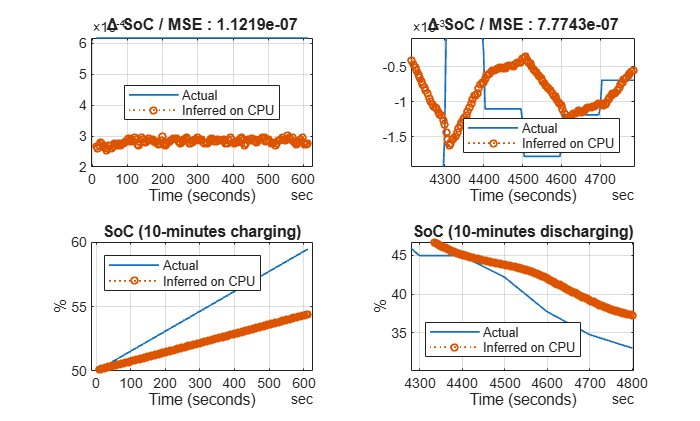

figH = figure; 
axH1all = copyobj([axH01, axH02, axH03, axH04], figH);

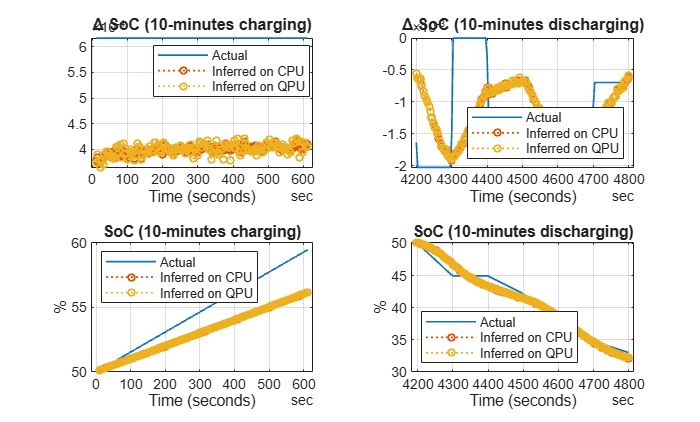

axH11 = axH1all(1);
hold(axH11, "on")
plot(axH11, socDiffTable.Time(idxChargeS:idxChargeE), ScaleFactorYn*yHatChargeQpu + OffsetYn, LineWidth = 1, LineStyle = ":", Marker = "o" ,MarkerSize = 4)
axH11.Title.String = "\Delta SoC (10-minutes charging)";
legend(axH11, ["Actual", "Inferred on CPU", "Inferred on QPU"], Location = "best");
hold(axH11, "off")

axH12 = axH1all(2);
hold(axH12, "on")
plot(axH12, socDiffTable.Time(idxDischgS:idxDischgE), ScaleFactorYn*yHatDischgQpu + OffsetYn, LineWidth = 1, LineStyle = ":", Marker = "o",MarkerSize = 4)
axH12.Title.String = "\Delta SoC (10-minutes discharging)";
legend(axH12, ["Actual", "Inferred on CPU", "Inferred on QPU"], Location = "southeast");
hold(axH12, "off")

axH13 = axH1all(3);
hold(axH13, "on")
plot(axH13, dataSocTT.Time(LagOrder:idxChargeE), dataSocTT.("SoC (Act)")(LagOrder) + [0; 100*cumsum(ScaleFactorYn*yHatChargeQpu + OffsetYn)], ...
    LineWidth = 1, LineStyle = ":", Marker = "o" ,MarkerSize = 4)
axH13.Title.String = "SoC (10-minutes charging)";
legend(axH13, ["Actual", "Inferred on CPU", "Inferred on QPU"], Location = "northwest");
hold(axH13, "off")

axH14 = axH1all(4);
hold(axH14, "on")
plot(axH14, dataSocTT.Time(idxDischgS-1:idxDischgE), dataSocTT.("SoC (Act)")(idxDischgS-1) + [0; 100*cumsum(ScaleFactorYn*yHatDischgQpu + OffsetYn)], ...
    LineWidth = 1, LineStyle = ":", Marker = "o" ,MarkerSize = 4)
axH14.Title.String = "SoC (10-minutes discharging)";
legend(axH14, ["Actual", "Inferred on CPU", "Inferred on QPU"], Location = "southwest");
hold(axH14, "off")

Fig.4 Comparing the result of inference on CPU and QPU 

We can see that there is high similarity between the inference results returned from the classical computer and the selected QPU device.